### 2.2 Applying DWT with the Wavelet Toolbox in MATLAB

clearvars; close all; clc;



% Parameters
fs = 512;               % Sampling Frequency (Hz)
N = 1024;               % Total number of samples

n = 0:N-1;              % Time index for the entire range

% Generating x1[n]
x1 = zeros(1, N);       % Initialize with zeros

% Piecewise waveform x1[n]
x1(1:512) = 2 * sin(20 * pi * n(1:512) / fs) + sin(80 * pi * n(1:512) / fs);
x1(513:end) = 0.5 * sin(40 * pi * n(513:end) / fs) + sin(60 * pi * n(513:end)/ fs);

% Generating x2[n]
x2 = zeros(1, N);       % Initialize with zeros

% Piecewise values for x2[n]
x2(1:64) = 1;
x2(64:128) = 2;
x2(128:512) = -1;
x2(512:704) = 3;
x2(704:960) = 1;

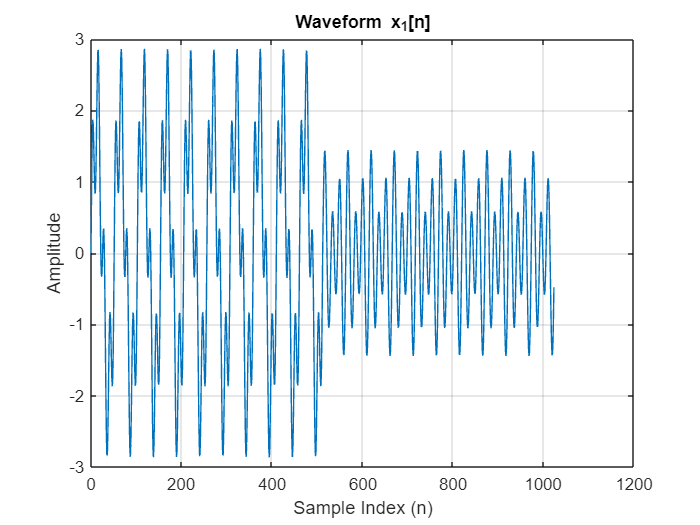

% Plotting x1[n]
figure;
plot(n, x1);
xlabel('Sample Index (n)');
ylabel('Amplitude');
title('Waveform x_{1}[n]');
grid on;

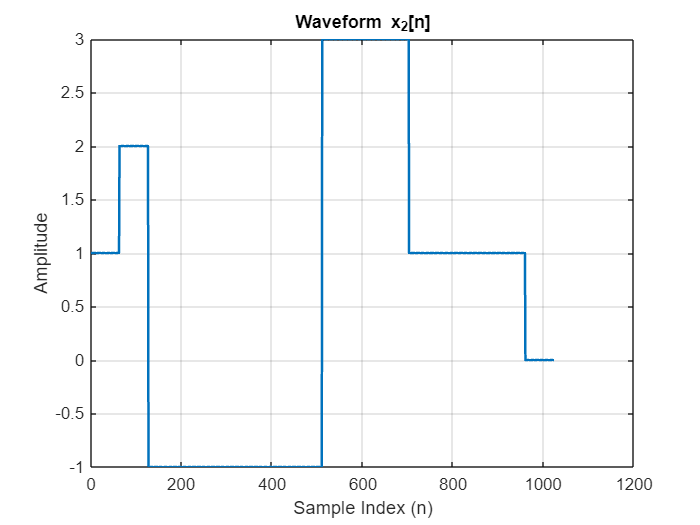

% Plotting x2[n]
plot(n, x2, 'LineWidth', 1.5);
xlabel('Sample Index (n)');
ylabel('Amplitude');
title('Waveform x_{2}[n]');
grid on;

% Add AWGN with 10 dB SNR
SNR = 10;
y1 = awgn(x1, SNR, 'measured');
y2 = awgn(x2, SNR, 'measured');

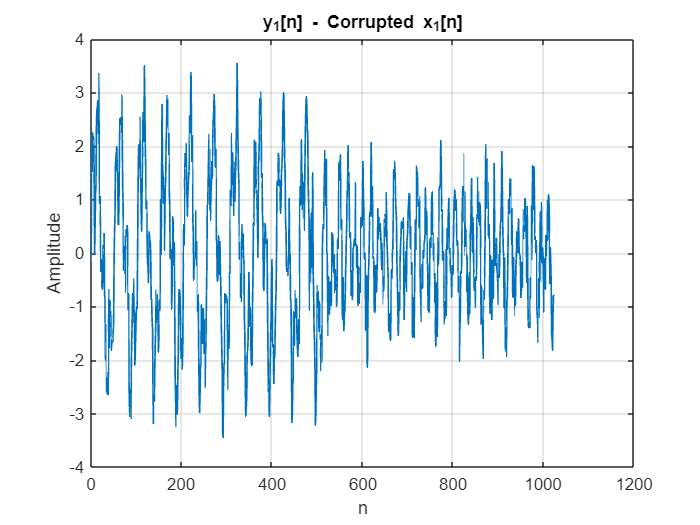

% Plot  y1[n] 
figure;
plot(n, y1, 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('y_{1}[n] - Corrupted x_{1}[n]');
grid on;

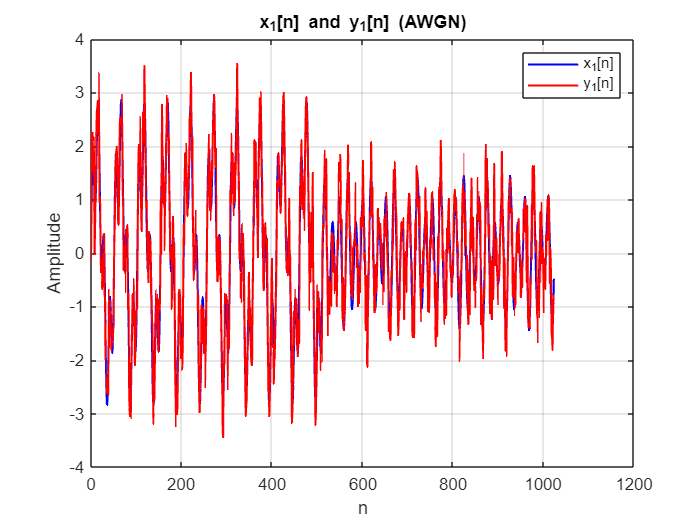

% Plot x1[n] and y1[n] on the same figure
figure;
plot(n, x1, 'b', 'LineWidth', 1.2); hold on;
plot(n, y1, 'r', 'LineWidth', 1.2);
xlabel('n'); ylabel('Amplitude');
title('x_{1}[n] and y_{1}[n] (AWGN)');
legend('x_{1}[n]', 'y_{1}[n]');
grid on;

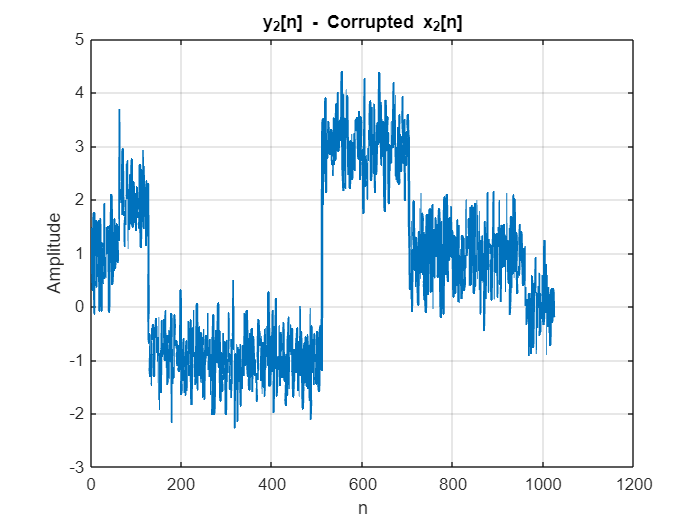

% Plot y2[n] 
figure;
plot(n, y2, 'LineWidth', 1.5);
xlabel('n'); ylabel('Amplitude');
title('y_{2}[n] - Corrupted x_{2}[n]');
grid on;

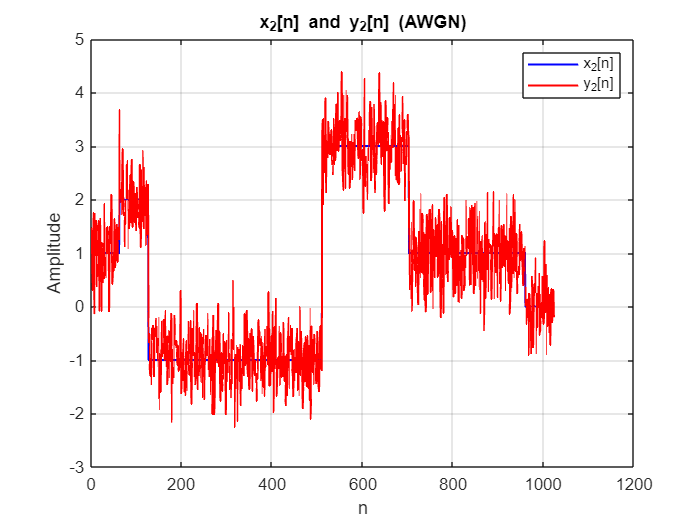

% Plot x2[n] and y2[n] on the same figure
figure;
plot(n, x2, 'b', 'LineWidth', 1.2); hold on;
plot(n, y2, 'r', 'LineWidth', 1.2);
xlabel('n'); ylabel('Amplitude');
title('x_{2}[n] and y_{2}[n] (AWGN)');
legend('x_{2}[n]', 'y_{2}[n]');
grid on;

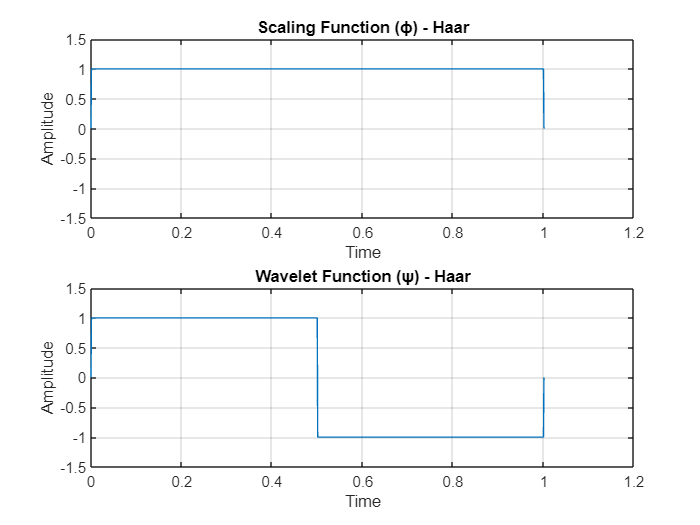

% Haar Wavelet and Scaling Function
[phi_haar, psi_haar, x_haar] = wavefun('haar', 10);  % 10 iterations for finer detail

figure;
subplot(2,1,1);
plot(x_haar, phi_haar);
title('Scaling Function (ϕ) - Haar');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.5 1.5]);
grid on;


subplot(2,1,2);
plot(x_haar, psi_haar);
title('Wavelet Function (ψ) - Haar');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.5 1.5]);
grid on;

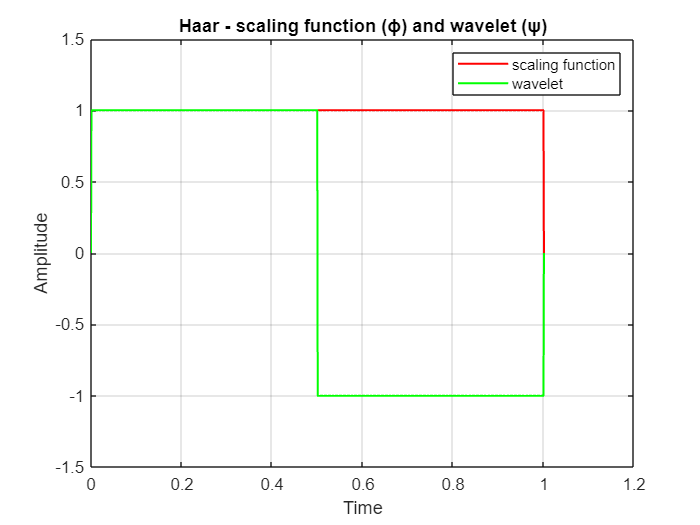

% Plot scaling function and wavelet on the same figure
figure;
plot(x_haar, phi_haar, 'r', 'LineWidth', 1.2); hold on;
plot(x_haar, psi_haar, 'g', 'LineWidth', 1.2);
xlabel('Time'); ylabel('Amplitude');
title('Haar - scaling function (ϕ) and wavelet (ψ)');
legend('scaling function', 'wavelet');
grid on;

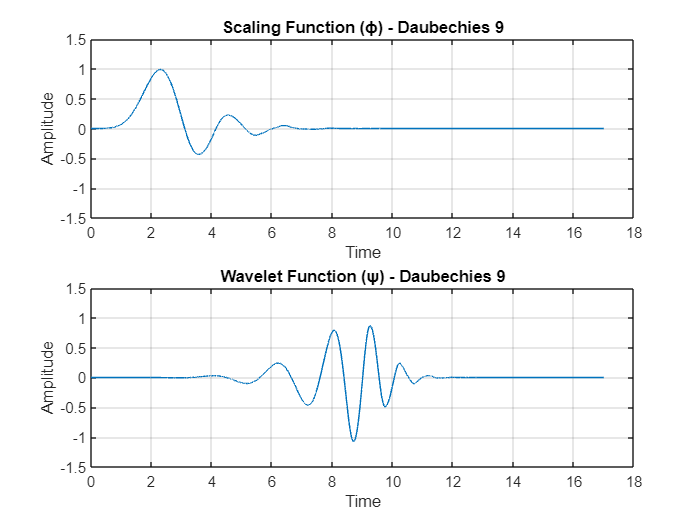


% Daubechies 9 Wavelet and Scaling Function
[phi_db9, psi_db9, x_db9] = wavefun('db9', 10);  % Tap 9

figure;
subplot(2,1,1);
plot(x_db9, phi_db9);
title('Scaling Function (ϕ) - Daubechies 9');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.5 1.5]);
grid on;

subplot(2,1,2);
plot(x_db9, psi_db9);
title('Wavelet Function (ψ) - Daubechies 9');
xlabel('Time');
ylabel('Amplitude');
ylim([-1.5 1.5]);
grid on;

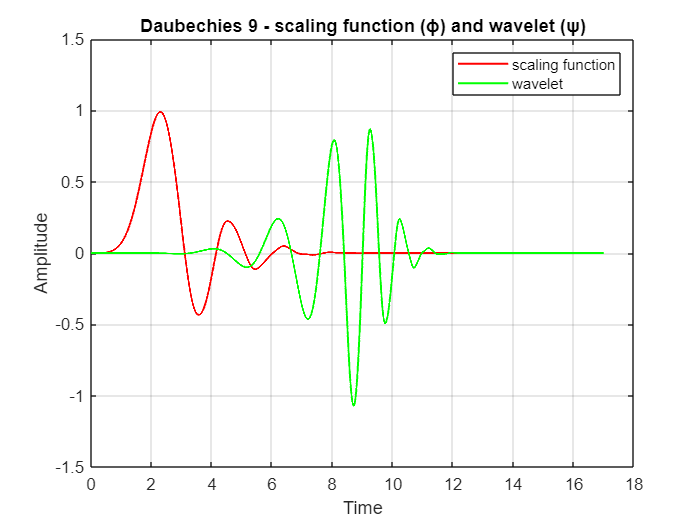

% Plot scaling function and wavelet on the same figure
figure;
plot(x_db9, phi_db9, 'r', 'LineWidth', 1.2); hold on;
plot(x_db9, psi_db9, 'g', 'LineWidth', 1.2);
xlabel('Time'); 
ylabel('Amplitude');
ylim([-1.5 1.5]);
title('Daubechies 9 - scaling function (ϕ) and wavelet (ψ)');
legend('scaling function', 'wavelet');
grid on;


% Level of decomposition
level = 10;

**Decomposition using Daubechies 9 wavelet**


% Decomposition using Daubechies 9 wavelet (y1)
[C_db9_y1, L_db9_y1] = wavedec(y1, level, 'db9');
% Display the coefficients and lengths
disp('Daubechies 9 Wavelet Decomposition Coefficients for y1:');

Daubechies 9 Wavelet Decomposition Coefficients for y1:


disp(C_db9_y1);

   42.7729   45.7621   46.0926   45.0838   45.5240   46.7460   44.2438   44.6103   45.4226   46.6895   44.1477   47.3859   42.7543   53.1698   22.9924  -15.0524  -26.8256    1.0252   -1.0533    0.8981   -1.1523   -0.3394   -0.6341   -3.2172  -10.2499   -6.1560   -0.8815    4.0057    7.0751   10.7502   -2.1840    2.5419   -0.6339    1.1641    1.0209   -1.1270    0.6959   -0.8605   -0.0215   -0.2032   -2.0491   -6.1043   -0.4786   -2.9102   -1.6323    2.3336    4.8451   -2.2159   10.2785   -3.2188    2.0867   -0.7191    0.5026   -0.6485    0.1724   -0.5607    0.0076    0.0068   -1.2097   -4.4963    0.2530    1.1167   -0.8660   -2.0170   -1.1670    1.9168    2.4936   -1.2573    0.2447   -0.1103    6.4375   -2.1450    0.3999   -0.5593    0.1892   -0.0407    0.1720   -0.1038   -1.0656   -3.8323   -0.6863    0.9025    0.3908    0.7736   -0.5039   -0.0762    0.3821    0.3771   -0.1039   -0.2426    0.1215   -0.8711    0.7388    0.0414   -1.1075   -0.2793   -0.2606    0.3285   -0.1079   -0.1191

disp('Lengths for each level:');

Lengths for each level:


disp(L_db9_y1);

          17          17          18          20          24          32          48          79         142         268         520        1024




% Details and the approximation
A10_y1_db9 = wrcoef('a', C_db9_y1, L_db9_y1, 'db9', 10); % Approximation 
D_y1_db9 = cell(1, level);
for k = 1:level
    D_y1_db9{k} = wrcoef('d', C_db9_y1, L_db9_y1, 'db9', k);
end

% Reconstruction y1
y1_recons_db9 = 0;
for i = 1:10
    y1_recons_db9 = y1_recons_db9 + D_y1_db9{i};
end

y1_recons_db9 = y1_recons_db9 + A10_y1_db9;

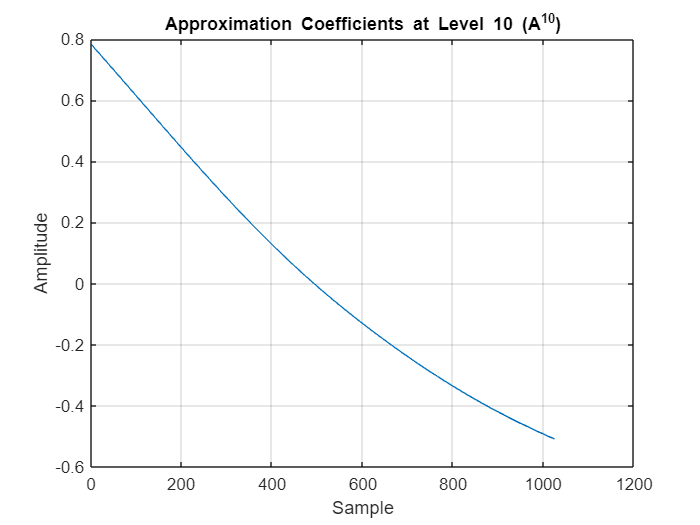

% Plot the approximation coefficient
figure;
plot(A10_y1_db9);
title('Approximation Coefficients at Level 10 (A^{10})', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

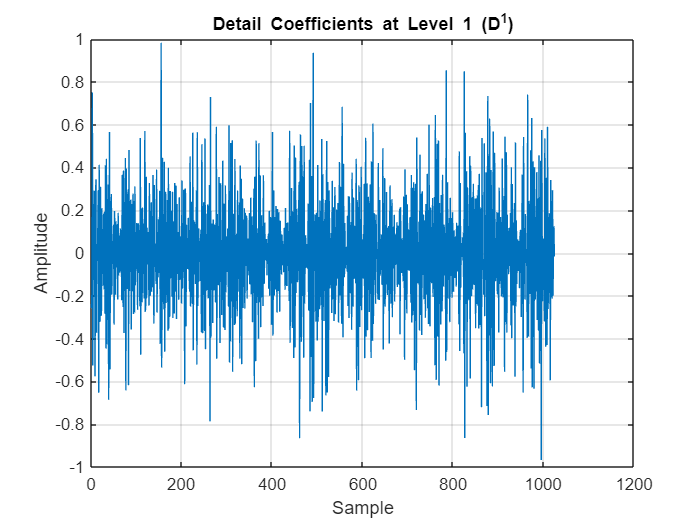

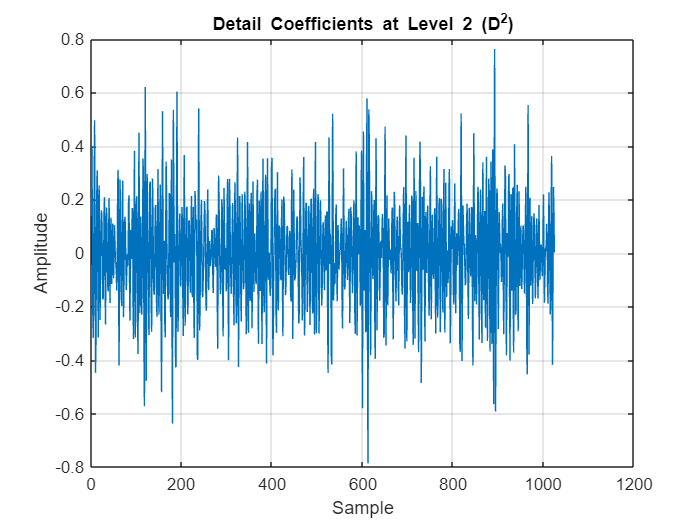

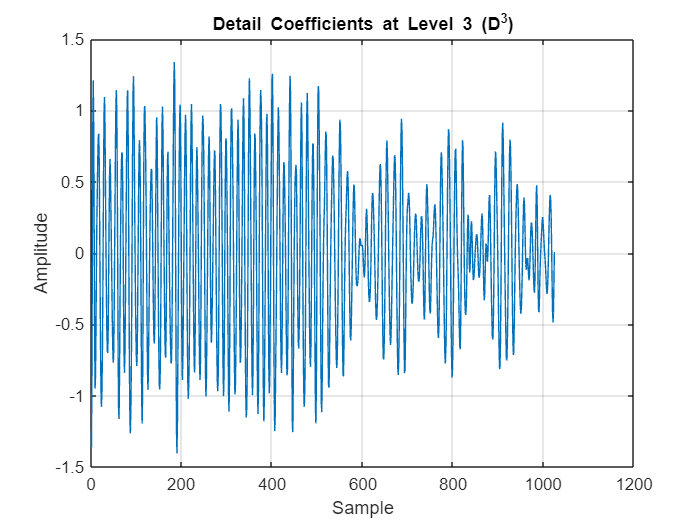

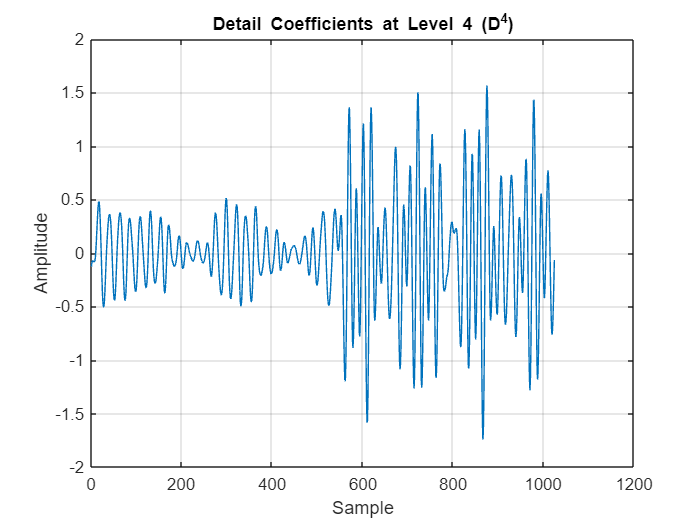

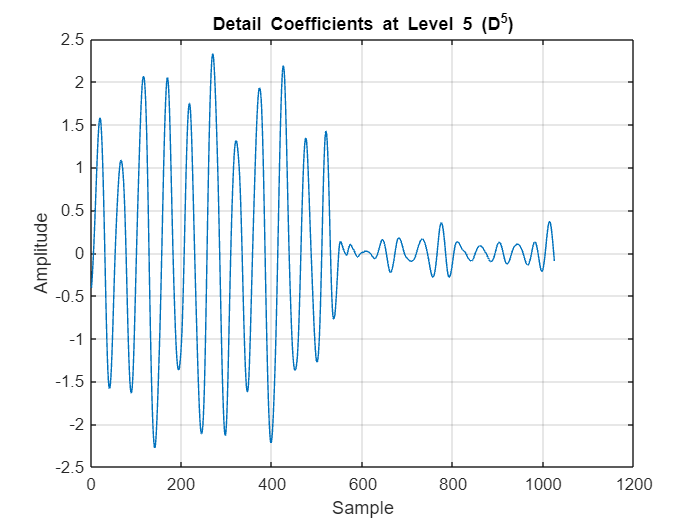

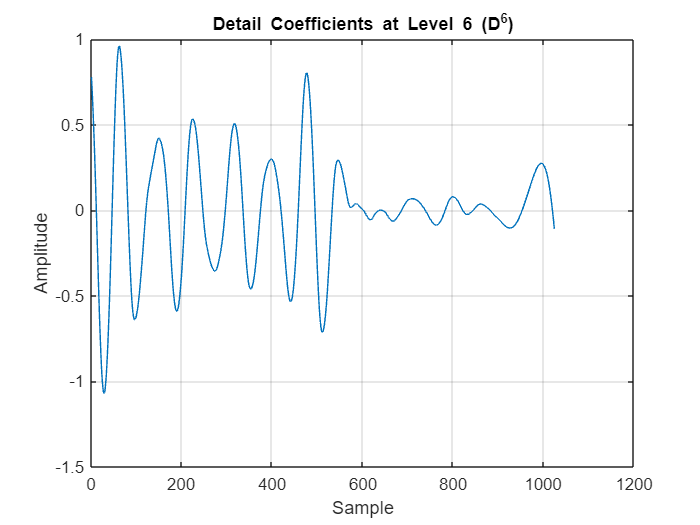

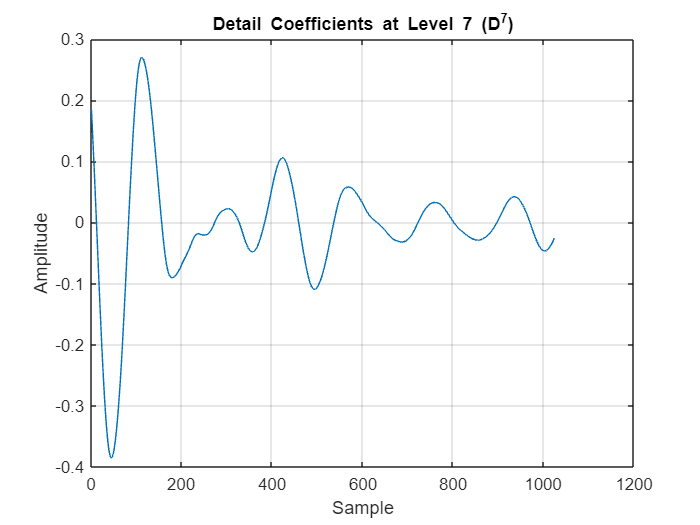

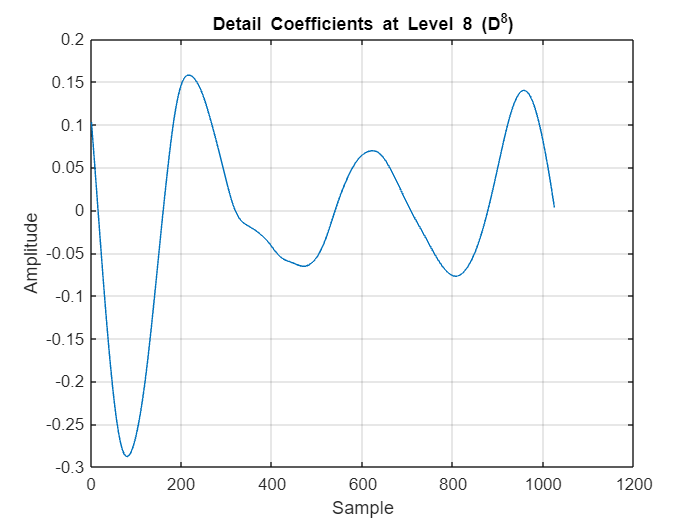


% Plot the detail coefficients for each level
for k = 1:level
    figure;
    plot(D_y1_db9{k});
    % Proper use of subscripts in the title
    title(['Detail Coefficients at Level ', num2str(k), ' (D^{', num2str(k), '})'], 'Interpreter', 'tex');
    xlabel('Sample');
    ylabel('Amplitude');
    grid on;
end

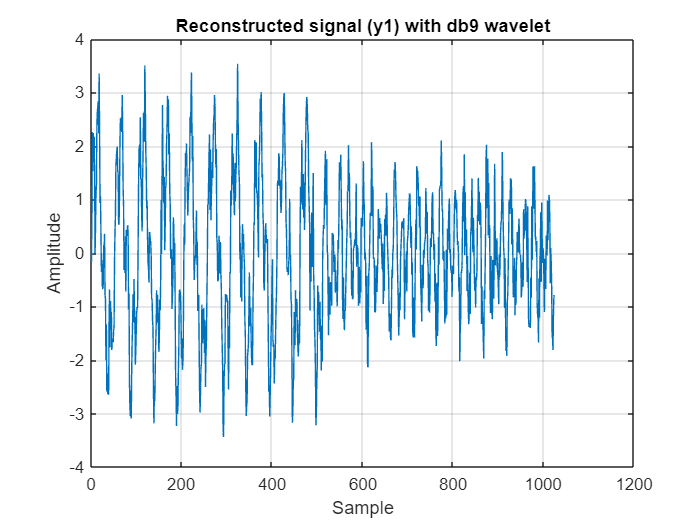

% Plot the reconstructed signal (y1)
figure;
plot(y1_recons_db9);
title('Reconstructed signal (y1) with db9 wavelet', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;


% Decomposition using Daubechies 9 wavelet (y2)
[C_db9_y2, L_db9_y2] = wavedec(y2, level, 'db9');
disp('Daubechies 9 Wavelet Decomposition Coefficients for y2:');

Daubechies 9 Wavelet Decomposition Coefficients for y2:


disp(C_db9_y2);

   31.1817   33.5266   33.3455   33.6541   33.2854   33.7083   32.8110   32.6740   33.4389   33.4518   33.2859   33.6315   34.0854   31.9973   29.0183    6.2618    7.2986    0.2029   -0.3607    0.1110    0.0568    0.0704   -0.5296   -4.4599  -18.0137  -21.3807    4.5370    2.0620   26.2601   11.3400   -0.2124    0.5142   -0.1930   -0.1726   -0.1366    0.1933   -0.0273    0.0586   -0.0500    0.0097    0.1214    2.0413   27.6670    4.1671   -9.1734    7.3169   -8.7616  -33.0731   14.4585   -6.8434    2.7758   -0.8079    0.0411   -0.0427    0.0053    0.0136    0.0498    0.1776    1.2471    5.9856   10.1171    7.8355    8.6466   -8.9271    4.5779   -1.6632    1.6639   -4.4154  -18.1944    0.1391   -8.7826    1.9484   -0.0938    0.1132   -0.0425   -0.0290   -0.0767   -0.0911   -0.1850   -0.7171   -6.9259   -1.0081    2.0604    7.0659    4.6223    1.7897   -0.8520    3.9782   -2.3825    1.2848   -3.0408    0.6645   -4.8985   -2.3386  -10.6886    5.5822    0.1096   -0.0947    0.1525    0.0042

disp('Lengths for each level:');

Lengths for each level:


disp(L_db9_y2);

          17          17          18          20          24          32          48          79         142         268         520        1024




% Extract approximation and detail coefficients for y2
A10_y2_db9 = wrcoef('a', C_db9_y2, L_db9_y2, 'db9', 10); % Approximation 
D_y2_db9 = cell(1, level);
for k = 1:level
    D_y2_db9{k} = wrcoef('d', C_db9_y2, L_db9_y2, 'db9', k); 
end

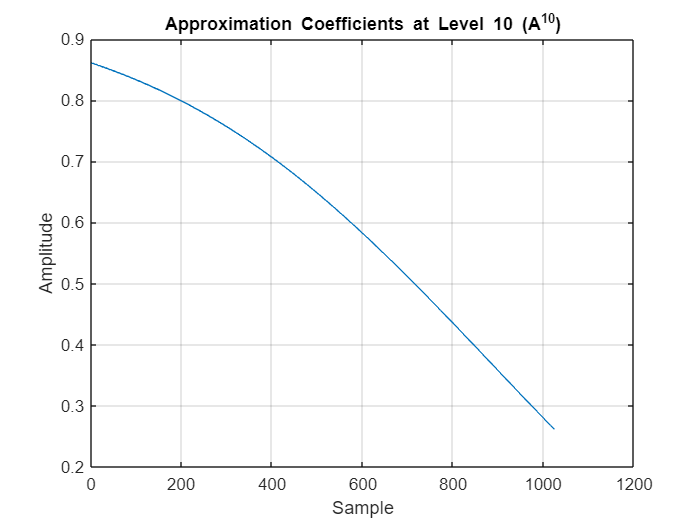

% Plot the approximation coefficient
figure;
plot(A10_y2_db9);
title('Approximation Coefficients at Level 10 (A^{10})', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

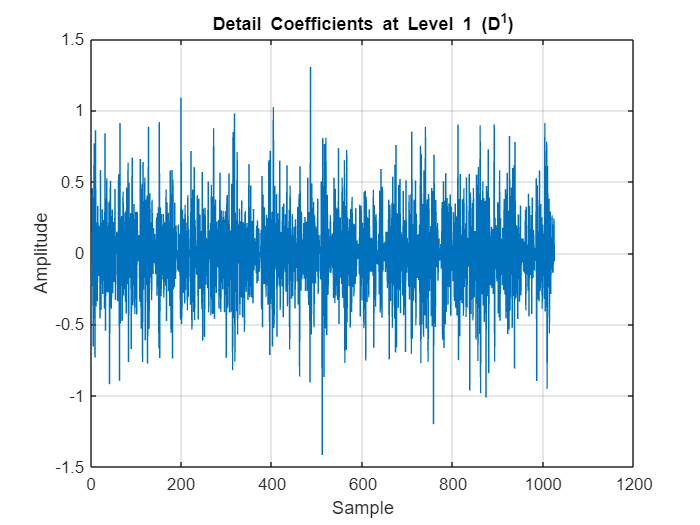

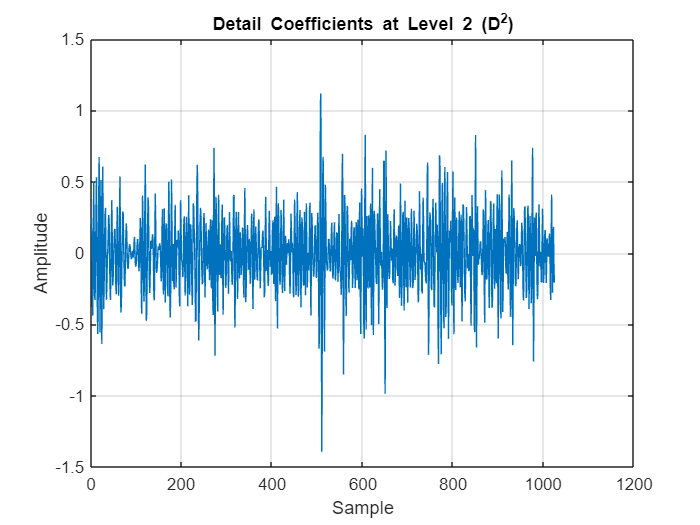

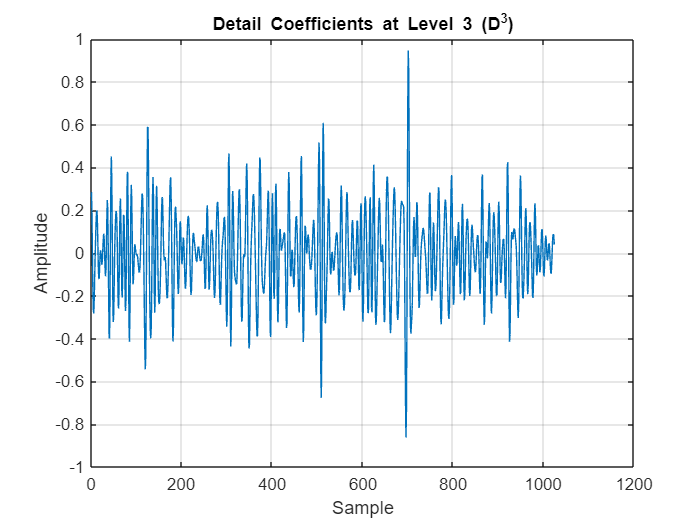

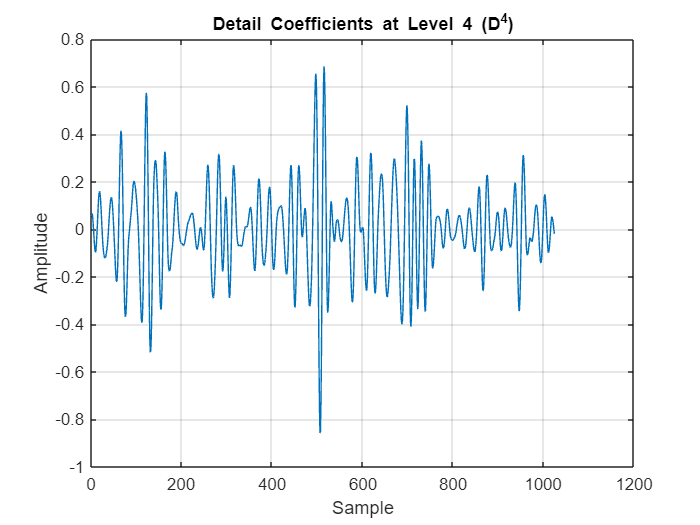

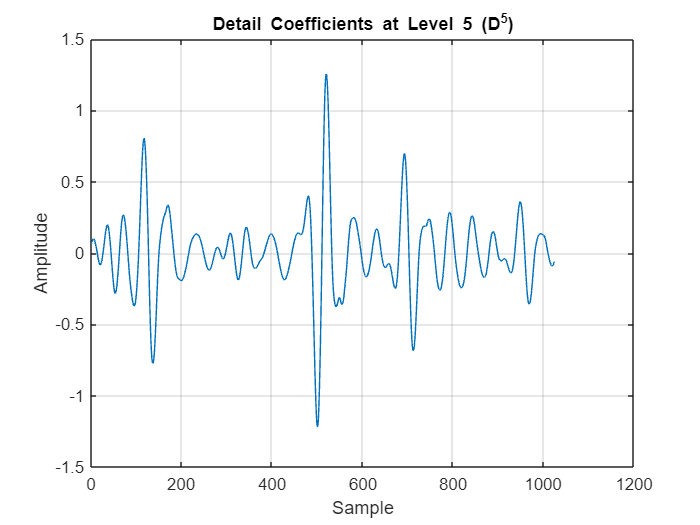

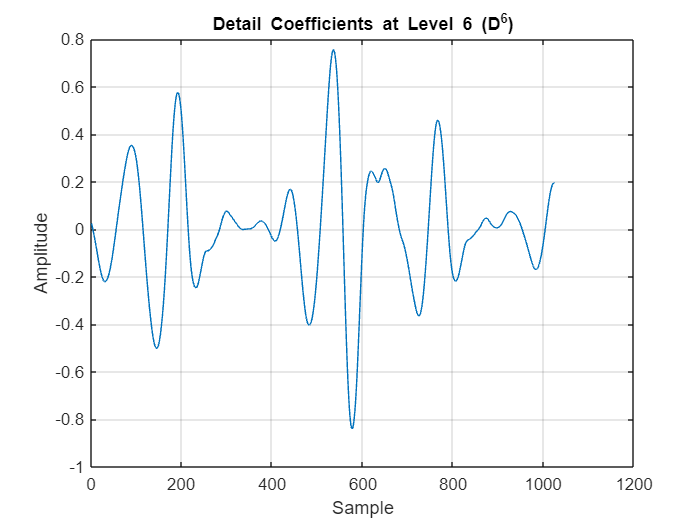

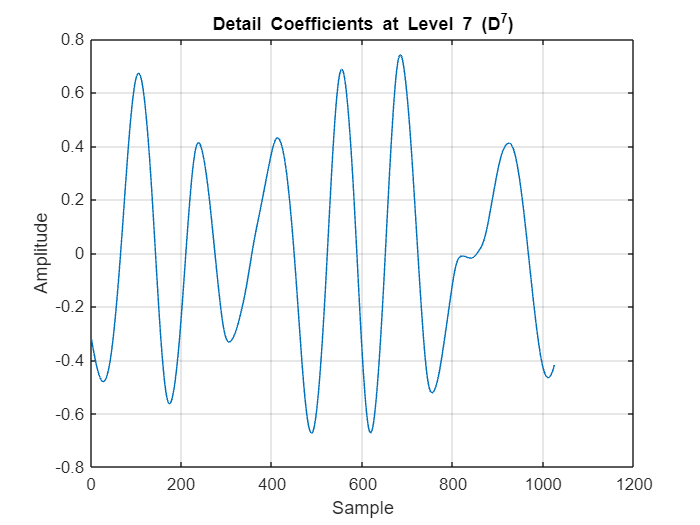

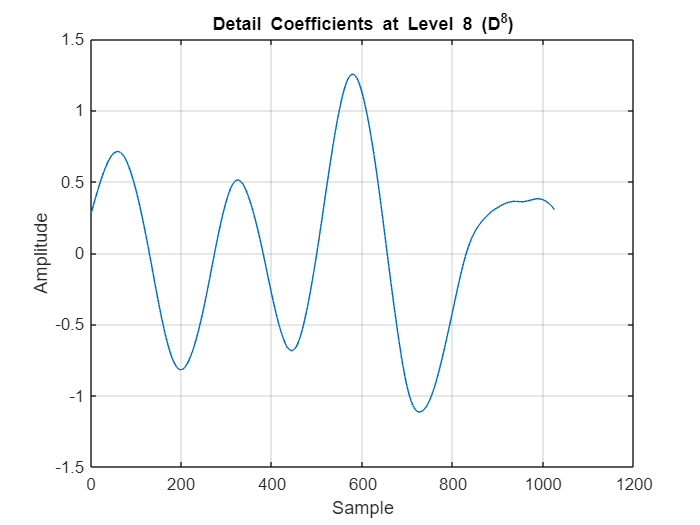


% Plot the detail coefficients for each level
for k = 1:level
    figure;
    plot(D_y2_db9{k});
    % Proper use of subscripts in the title
    title(['Detail Coefficients at Level ', num2str(k), ' (D^{', num2str(k), '})'], 'Interpreter', 'tex');
    xlabel('Sample');
    ylabel('Amplitude');
    grid on;
end

% Reconstruction y2
y2_recons_db9 = 0;
for i = 1:10
    y2_recons_db9 = y2_recons_db9 + D_y2_db9{i};
end

y2_recons_db9 = y2_recons_db9 + A10_y2_db9;


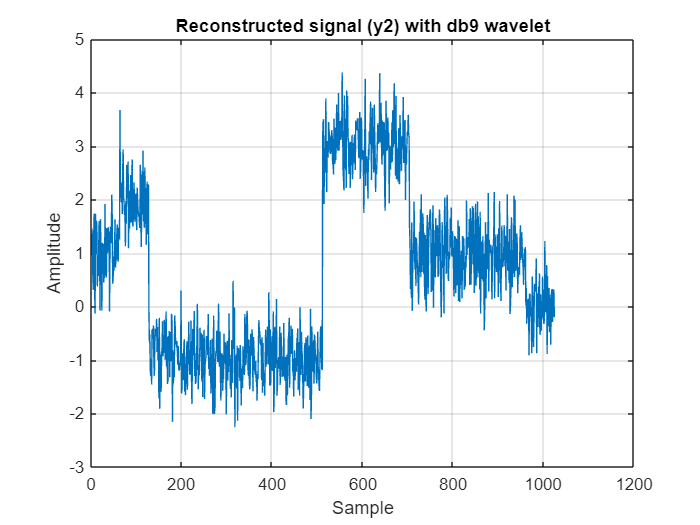

% Plot the reconstructed signal (y2)
figure;
plot(y2_recons_db9);
title('Reconstructed signal (y2) with db9 wavelet', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

**Decomposition using Haar wavelet**

% Decomposition using Haar wavelet
[C_haar_y1, L_haar_y1] = wavedec(y1, level, 'haar');
disp('Haar Wavelet Decomposition Coefficients for y1:');

Haar Wavelet Decomposition Coefficients for y1:


disp(C_haar_y1);

    0.1449   -0.1494   -0.1123    0.2708    4.2989    3.7329    0.7945    1.2235   -0.1958    0.0628    0.2120    0.1506    0.7813    0.3064    1.0966    0.7131    6.1499   -3.8568   -3.4332    5.6312    6.0882   -3.5168   -4.3000    4.9166   -1.1648    0.4441   -0.3836    0.4799   -0.1583    0.2420   -0.0030    0.1606    3.3533   -6.8435    7.2126   -3.2353   -2.9772    7.5875   -8.0630    4.2078    2.3960   -7.0815    6.8986   -3.1850   -1.6977    7.2139   -7.5568    4.1500    1.8974   -0.2889   -0.5908    0.5538    1.1959   -0.5491   -1.0770    0.8969    1.1440   -0.4292   -0.8456    0.9815    1.3603   -0.5901   -0.8667    0.6014   -0.3028    3.1381   -1.5801   -2.8141    4.2272   -0.0185   -5.5890    3.0474    3.9770   -4.0036   -1.0843    3.9772   -1.1590   -1.7552    2.2337   -0.6304   -0.8656    3.2327   -2.3124   -2.1779    4.5877    0.2439   -5.2079    2.3332    3.8494   -4.7263   -1.2266    3.5285   -0.9334   -2.2720    1.8648   -0.7521    2.7997    0.5299    2.5077   -1.4389

disp('Lengths for each level:');

Lengths for each level:


disp(L_haar_y1);

           1           1           2           4           8          16          32          64         128         256         512        1024




% Details and the approximation
A10_y1_haar = wrcoef('a', C_haar_y1, L_haar_y1, 'haar', 10); % Approximation 
D_y1_haar = cell(1, level);
for k = 1:level
    D_y1_haar{k} = wrcoef('d', C_haar_y1, L_haar_y1, 'haar', k);
end

% Reconstruction y1
y1_recons_haar = 0;
for i = 1:10
    y1_recons_haar = y1_recons_haar + D_y1_haar{i};
end

y1_recons_haar = y1_recons_haar + A10_y1_haar;

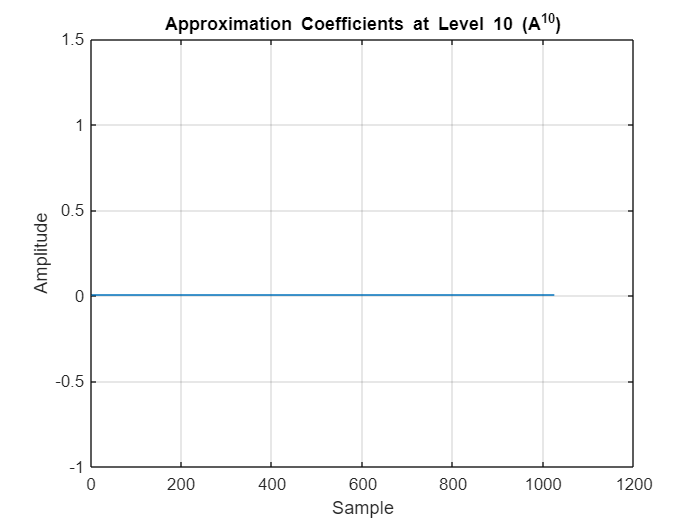

% Plot the approximation coefficient
figure;
plot(A10_y1_haar);
title('Approximation Coefficients at Level 10 (A^{10})', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

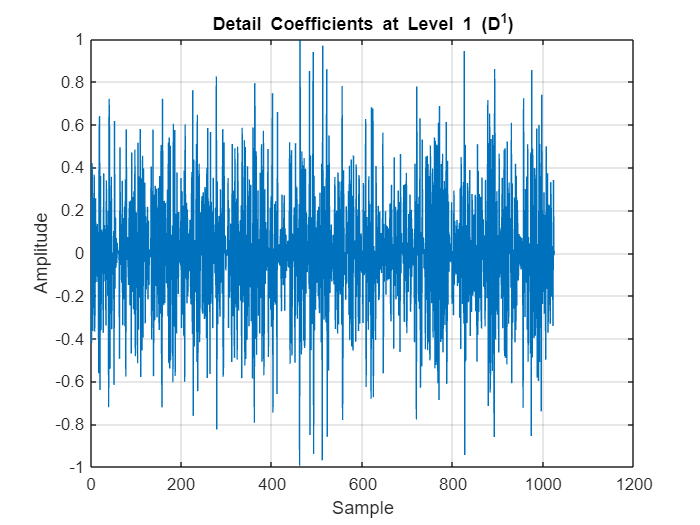

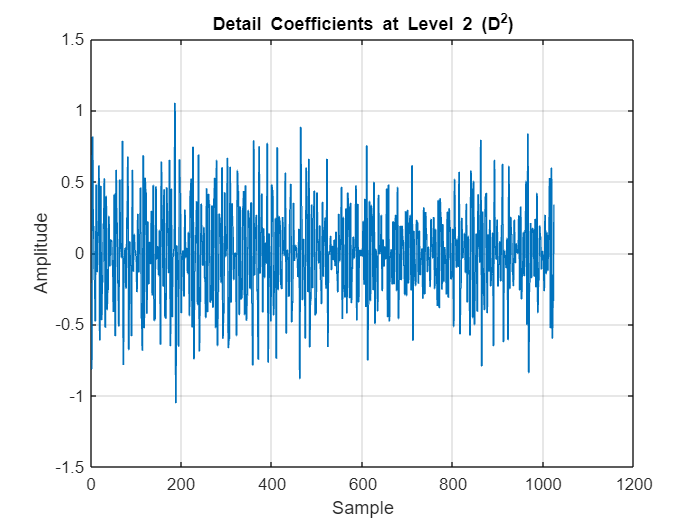

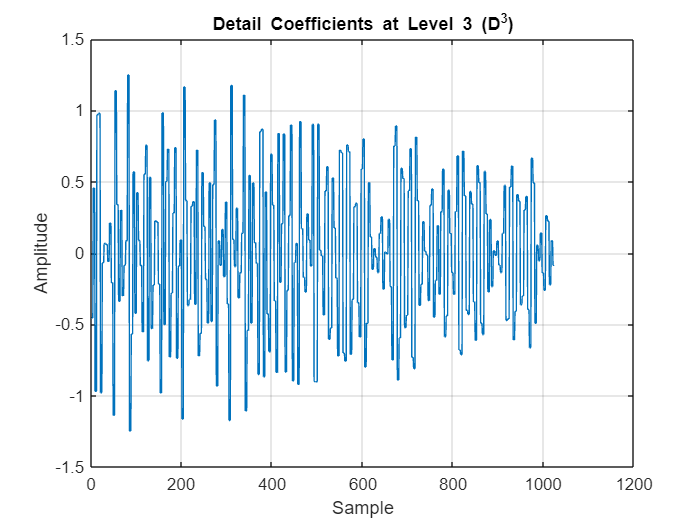

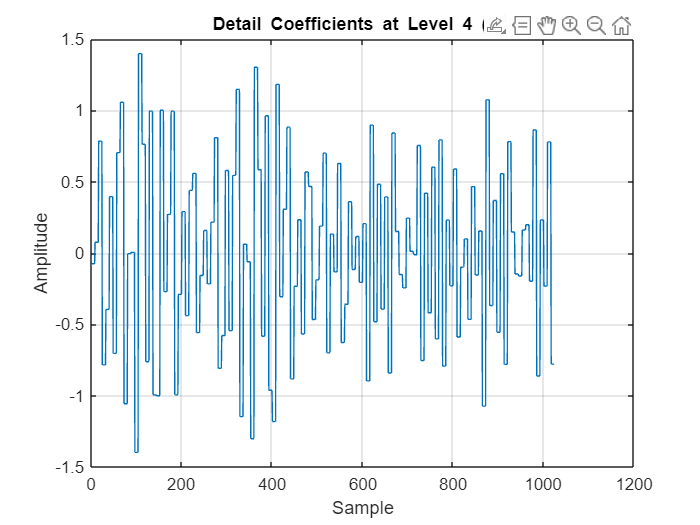

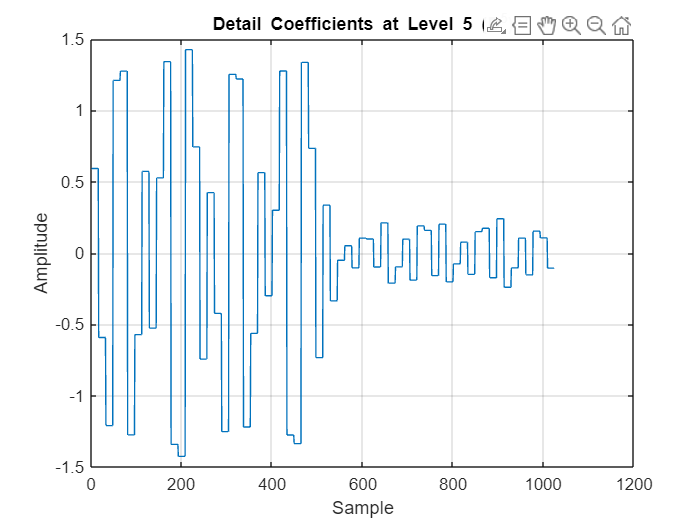

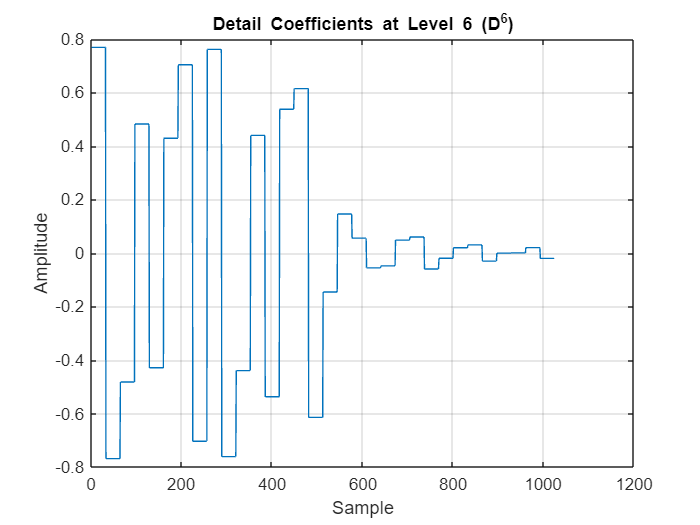

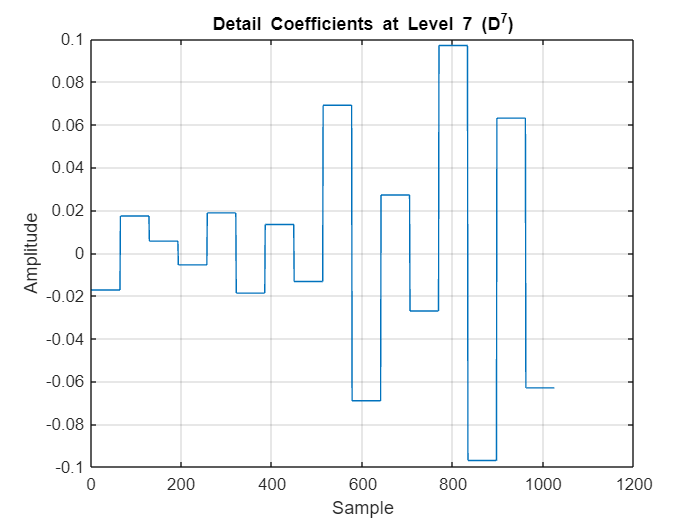

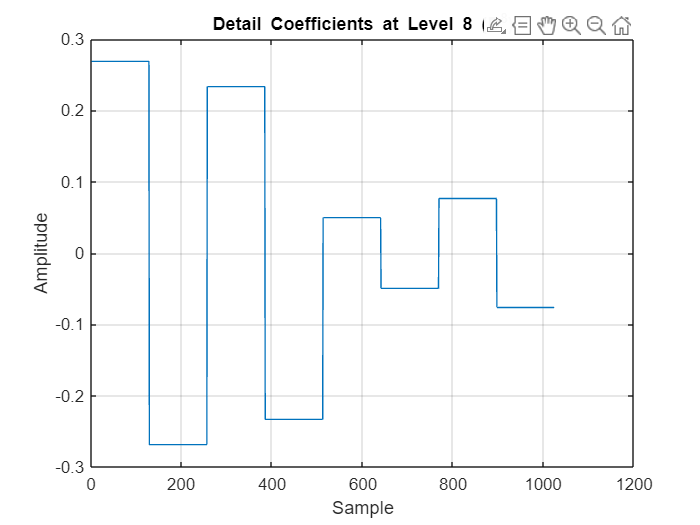


% Plot the detail coefficients for each level
for k = 1:level
    figure;
    plot(D_y1_haar{k});
    % Proper use of subscripts in the title
    title(['Detail Coefficients at Level ', num2str(k), ' (D^{', num2str(k), '})'], 'Interpreter', 'tex');
    xlabel('Sample');
    ylabel('Amplitude');
    grid on;
end

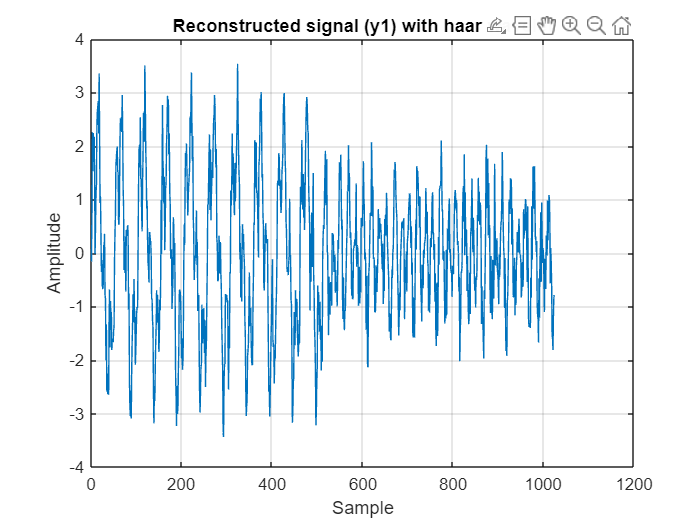

% Plot the reconstructed signal (y1)
figure;
plot(y1_recons_haar);
title('Reconstructed signal (y1) with haar wavelet', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

% Decomposition using Haar wavelet
[C_haar_y2, L_haar_y2] = wavedec(y2, level, 'haar');
disp('Haar Wavelet Decomposition Coefficients for y2:');

Haar Wavelet Decomposition Coefficients for y2:


disp(C_haar_y2);

   20.5744  -31.4289   14.4142   20.0665   19.0880   -0.5073    8.3568    4.1457   -4.7268    0.8044    0.0495    0.0765    0.3243   11.4240   -0.1858    5.4578   -0.9470    0.7787   -0.0783   -0.6668   -0.0990   -0.0818    0.4462   -0.3596   -0.3678   -0.0965    0.6177   -0.0928    1.1032    0.7563   -0.3400   -0.1074    0.2548   -0.2066    0.1422   -0.0558    0.2803    0.1921    0.0406   -0.1550   -0.1018   -0.4573   -0.8424   -0.2579    0.5871   -0.5327    0.2156   -0.7185   -0.3196    0.4066    0.3413   -0.1829   -0.1787   -0.4058   -0.2608   -0.0578   -0.3251   -0.1634    0.4074   -0.4612    0.1647    0.3111   -0.1776   -0.0162    0.2949   -0.1567   -0.0342   -1.2935    0.7218   -0.0625    0.2898    0.7968   -0.4232    0.0836    0.4981   -0.7607    0.3651    0.2533    0.0942    0.1240    0.7428   -0.4617    0.1523   -0.3405    0.2615    0.3905    0.9334    1.2079   -0.1490   -0.1105    0.6224    0.0054   -0.0640   -0.3962   -0.4796   -1.4783   -0.0297   -0.5726    0.1121    0.8558

disp('Lengths for each level:');

Lengths for each level:


disp(L_haar_y2);

           1           1           2           4           8          16          32          64         128         256         512        1024




% Details and the approximation
A10_y2_haar = wrcoef('a', C_haar_y2, L_haar_y2, 'haar', 10); % Approximation 
D_y2_haar = cell(1, level);
for k = 1:level
    D_y2_haar{k} = wrcoef('d', C_haar_y2, L_haar_y2, 'haar', k);
end

% Reconstruction y1
y2_recons_haar = 0;
for i = 1:10
    y2_recons_haar = y2_recons_haar + D_y2_haar{i};
end

y2_recons_haar = y2_recons_haar + A10_y2_haar;

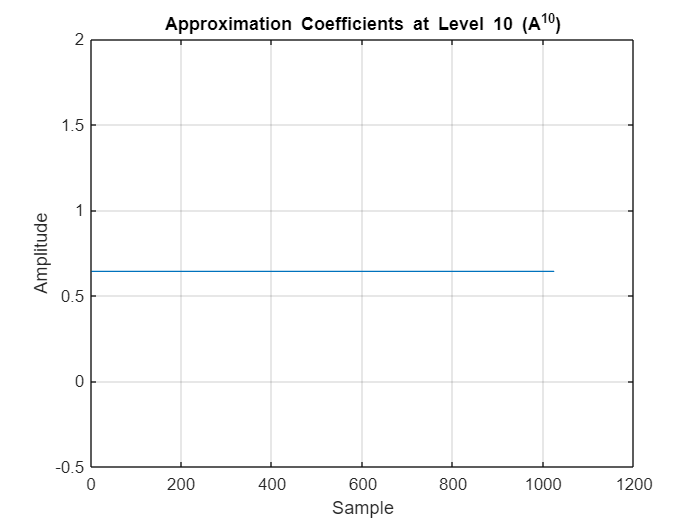

% Plot the approximation coefficient
figure;
plot(A10_y2_haar);
title('Approximation Coefficients at Level 10 (A^{10})', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

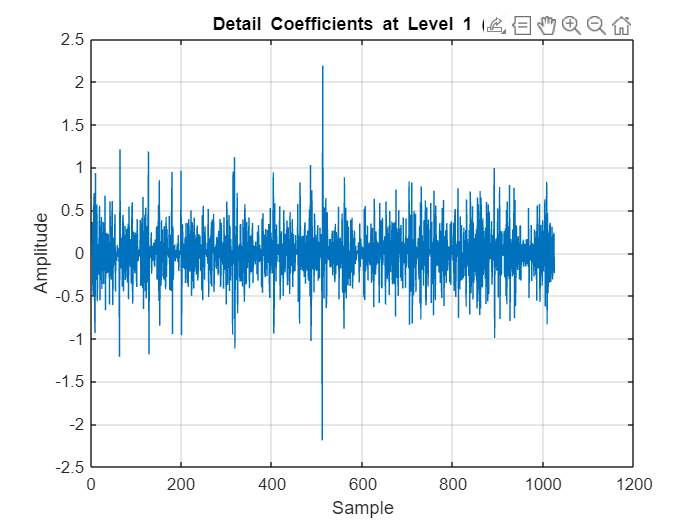

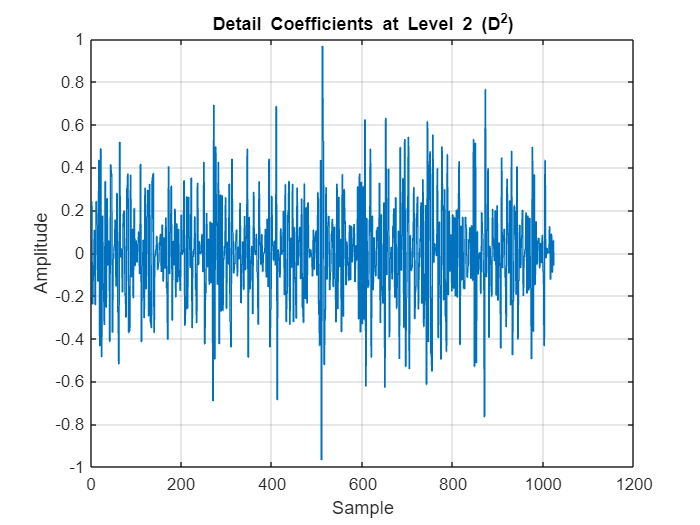

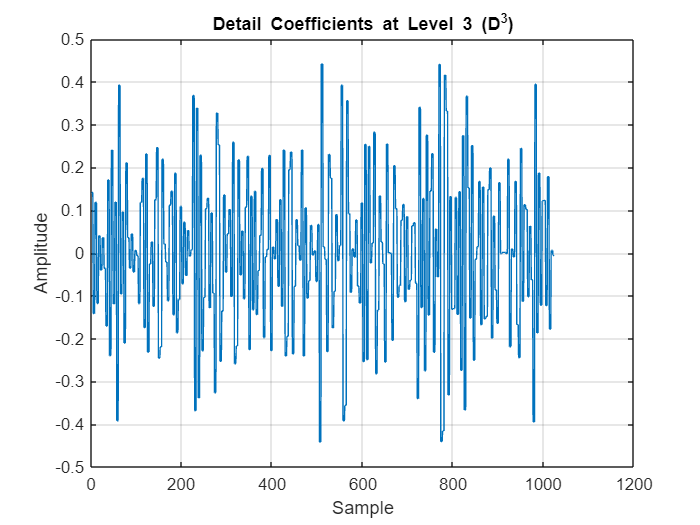

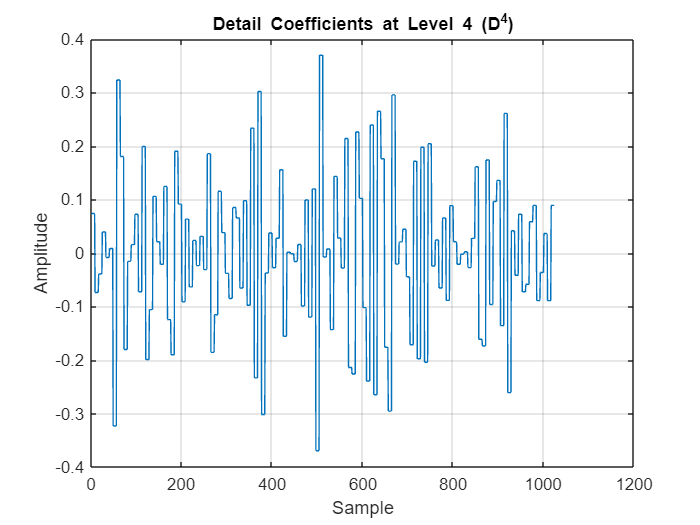

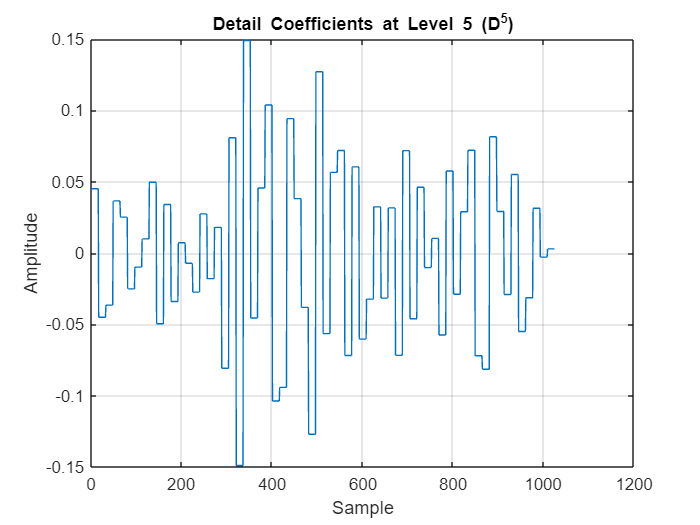

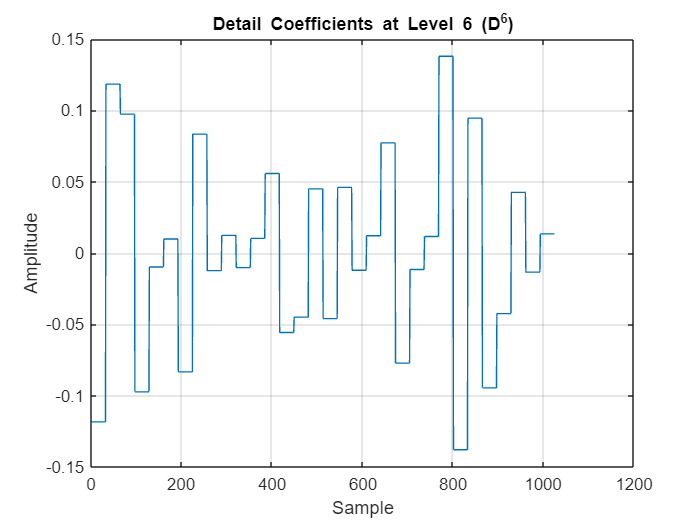

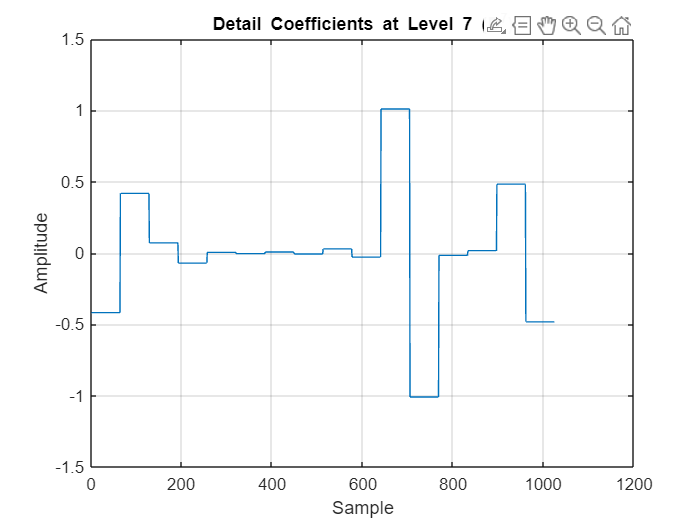

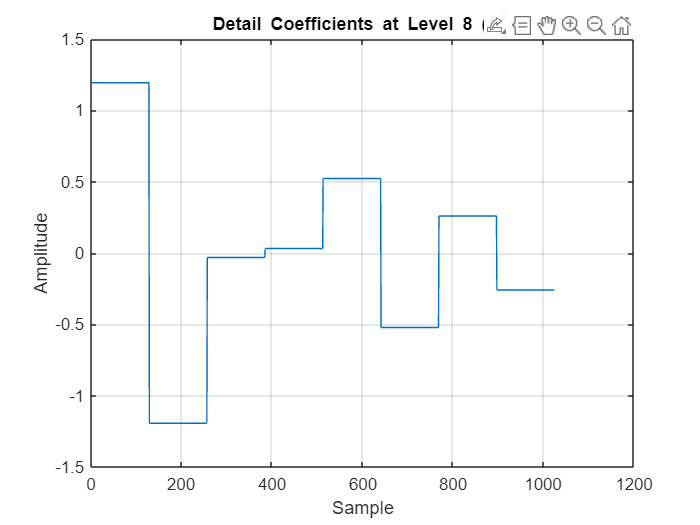


% Plot the detail coefficients for each level
for k = 1:level
    figure;
    plot(D_y2_haar{k});
    % Proper use of subscripts in the title
    title(['Detail Coefficients at Level ', num2str(k), ' (D^{', num2str(k), '})'], 'Interpreter', 'tex');
    xlabel('Sample');
    ylabel('Amplitude');
    grid on;
end

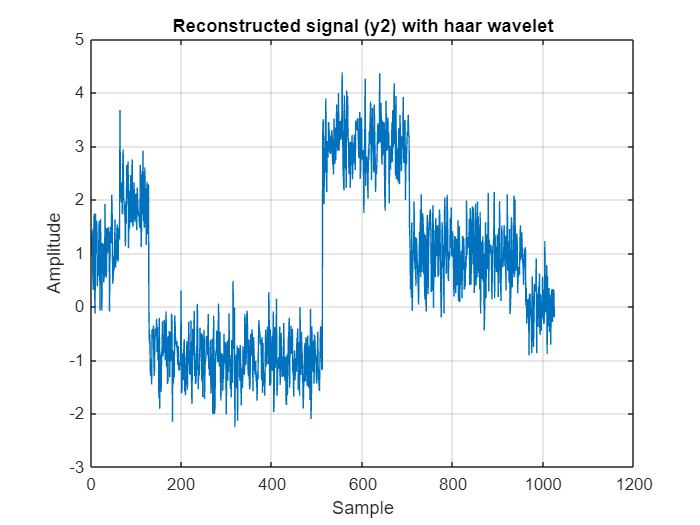

% Plot the reconstructed signal (y1)
figure;
plot(y2_recons_haar);
title('Reconstructed signal (y2) with haar wavelet', 'Interpreter', 'tex');
xlabel('Sample');
ylabel('Amplitude');
grid on;

#### Energy differences

% Energy difference between y1 and reconstructed y1 using db9
energy_diff_y1_db9 = sum(y1.^2) - sum(y1_recons_db9.^2);

% Energy difference between y2 and reconstructed y2 using db9
energy_diff_y2_db9 = sum(y2.^2) - sum(y2_recons_db9.^2);

% Energy difference between y1 and reconstructed y1 using haar
energy_diff_y1_haar = sum(y1.^2) - sum(y1_recons_haar.^2);

% Energy difference between y2 and reconstructed y2 using haar
energy_diff_y2_haar = sum(y2.^2) - sum(y2_recons_haar.^2);



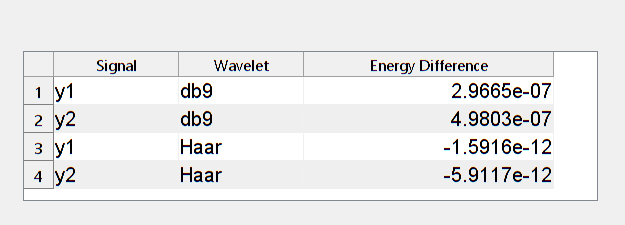

% Define the energy difference data
energy_diff_data = {
    'y1', 'db9', abs(energy_diff_y1_db9);
    'y2', 'db9', abs(energy_diff_y2_db9);
    'y1', 'Haar', abs(energy_diff_y1_haar);
    'y2', 'Haar', abs(energy_diff_y2_haar);
};

% Create a new figure for the table
fig = figure('Name', 'Energy Differences', ...
             'NumberTitle', 'off', ...
             'Position', [300, 300, 500, 180]); % Adjust the figure position and size

% Add a uitable to the figure
uitable('Parent', fig, ... % Set the figure as the parent of the table
        'Data', energy_diff_data, ...
        'ColumnName', {'Signal', 'Wavelet', 'Energy Difference'}, ...
        'ColumnWidth', {100, 100, 200}, ...
        'Position', [20, 20, 460, 120], ... % Position and size of the table
        'FontSize', 12); % Optional: Adjust font size for better readability